## **Przetwarzanie Sygnałów Cyfrowych**

# Analiza harmoniczna cz. 2

## Jan Rosa 410269 AiR

## Ćwiczenie 1

Transformata fouriera sygnału sin(wt)

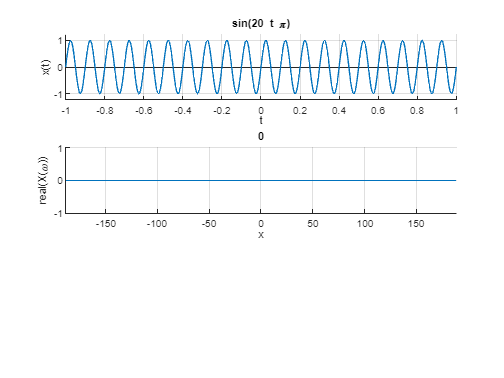

Error using symengine
Unable to convert expression containing symbolic variables into double array. Apply 'subs' function first to substitute values for variables.

Error in sym/double (line 872)
        Xstr = mupadmex('symobj::double', S.s, 0);

Error in Lab_5>fourT (line 50)
ylim([min(double(X_FT)) max(doubl

syms t
f0 = 10; %Hz
w0 = 2*pi*f0;
x = sin(w0*t);
fourT(x, f0)

## Zad 2

### a) sygnaª cos(ω0t)

f0 = 10; %Hz
w0 = 2*pi*f0;
x = cos(w0*t);
fourT(x, f0)

### b) sygnaª staªy o warto±ci 10 (do jego zde�niowanie nale»y u»y¢ polecenia sym(10))

f0 = 1; %Hz
x = sym(10);
fourT(x, f0)

### c) skok jednostkowy o amplitudzie 1

f0 = 1; %Hz
x = dirac(t);
fplot(x,[-1,1])
fourT(x, f0)

### d) impuls prostok¡tny o amplitudzie 1 oraz czasie trwania Ti = 2/f0

f0 = 2;
x = rectangularPulse(-1, 1, t)
fourT(x, f0)


### e) impuls trójk¡tny (symetryczny) o amplitudzie 1 oraz czasie trwania Ti = 2/f0 .

f0 = 1;
x = triangularPulse(-1/f0, 1/f0, t)
fourT(x, f0)

function [] = fourT(x, f0)

syms w t w0 X_FT

w0 = 2*pi*f0;

BND_t = [-10/f0;10/f0]; %20 okresow
t_SMP = [BND_t(1):1/(10*f0):BND_t(2) ];
BND_w = [-3*w0;3*w0];
w_SMP = [BND_w(1):w0/10:BND_w(2) ];


X_FT = fourier(x);

figure
subplot(3,1,1); ylabel('x(t)'); hold on
ezplot(x,BND_t); hold on; grid on;
v_num = subs(x, t, t_SMP);
n = find(abs(v_num) == inf); % plot dirac (inf)
stem(t_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);

subplot(3,1,2); ylabel('real(X(\omega))'); hold on
ezplot(real(X_FT), BND_w); hold on; grid on;
v_num = subs(real(X_FT), w, w_SMP);
n = find( abs(v_num) == inf); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
    
subplot(3,1,3); ylabel('imag(X(\omega))'); hold on
ezplot(imag(X_FT), BND_w); hold on; grid on
v_num = subs(imag(X_FT), w, w_SMP);
n = find( abs(v_num) == inf ); % plot dirac (inf)
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
end